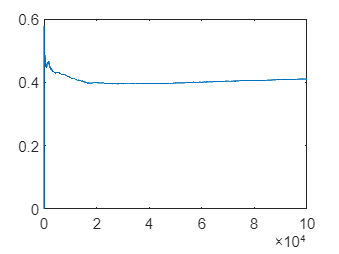

% define algorithm parameters
alpha = 0.5;
gamma = 1;
epsilon = 0.1;

% Note a the grid position and its attribution as:
% s=(i,j,b), i,j=1 to 3. b=1 when the opponent has placed a mark on it.
% b=2 when no one has placed a mark on it. 
% b=3 when the algorithm has placed a mark on it.
% Let S be the set of s for all grid positions.
% For simplicity, define S(i,j)=b which refers to s=(i,j,b)
% Possible actions A: place a mark on any grid haven't been marked before. 
% For simplicity, use the possible grid position (ia,ja) to refer to the  
% action of place a mark on position (ia,ja).
% Q(S,A) = Q(S, [ia ja]), where S is a 3*3 matrix.
% Q(S,A) can be reshaped as an 11-dimension array, each dimension has 3 
% possible values, which is easier for calculation.


%%% Initialise S arbitrarily
S = zeros(3);
Q = zeros(3*ones(1,11));
pol = zeros(3*ones(1,11));

% specify the number of episodes
N = 1000000;

% return per episode
rets = zeros(N,1);
winrate = zeros(N,1);

%%% Repeat for each episode
for i = 1:N

    %%% Initialise S
    % begin in the start state
    S = 2*ones(3);

    % we want to keep going unless in a terminal state;
    term = false;

    %%% Repeat for each step of episode

    % reset episode return
    ret = 0;

    % random player goes first
    if(rand>0.5)
        S(randi(3),randi(3))=1;
    end

    while term == false

        % Possible actions A
        A = checkUnmarked(S);
        if isempty(A)
            term = true;
            R = 0;
            break
        end
        
        % if not initialised
        if pol(S(1,1),S(1,2),S(1,3),S(2,1),S(2,2),S(2,3),S(3,1),S(3,2),S(3,3),A(1,1),A(1,2)) == 0
            % the policy is initialised to equal probabilities for all actions
            p = zeros(3);
            for m = 1:length(A(:,1))
                p(A(m,1),A(m,2)) = 1/length(A(:,1));
            end
            
            % for convenience the policy is stored as a cumulative probability
            % distribution over actions 
            pol(S(1,1),S(1,2),S(1,3),S(2,1),S(2,2),S(2,3),S(3,1),S(3,2),S(3,3),:,:) = reshape(cumsum(reshape(p',1,9)),3,3)';
        end

        %%% Choose A from S using policy derived from Q
        % generate a uniform random number in (0,1)
        r = rand;
    
        % find the interval of the cumulative distribution in which r falls to
        % determine the action
        % e.g. if we have the following cumulative probability distribution on
        % [0,1] and some value of r in (0,1)
        %
        % 0        pol(S,1)  pol(S,2)       pol(S,3)   pol(S,4)=1
        % |--------|-----------|-----------|----|------------|
        %                                  r
        % then we are taking action 3: note we have
        % pol(i,j,2)-r<0
        % but
        % pol(i,j,3)-r>0

        % Find the first value among A such that pol-r>0
        tmp = reshape(pol(S(1,1),S(1,2),S(1,3),S(2,1),S(2,2),S(2,3),S(3,1),S(3,2),S(3,3),:,:),3,3);
        ak = find((reshape(tmp',1,9)-r)>0,1);
        ac(1) = ceil(ak/3);
        ac(2) = mod(ak,3) + 3*(mod(ak,3)==0);

        %%% Take action A, observe Sp and R
        [Sp,R,term] = next_state(S,ac);

        %%% Find an action to maximise Q(Sp,a)
        M = max(Q(Sp(1,1),Sp(1,2),Sp(1,3),Sp(2,1),Sp(2,2),Sp(2,3),Sp(3,1),Sp(3,2),Sp(3,3),:,:));
        argmaxa = find(Q(Sp(1,1),Sp(1,2),Sp(1,3),Sp(2,1),Sp(2,2),Sp(2,3),Sp(3,1),Sp(3,2),Sp(3,3),:,:) == M);
        a = argmaxa(randi(length(argmaxa)));
        ad(2) = ceil(a/3);
        ad(1) = mod(a,3) + 3*(mod(a,3)==0);

        %%% Update Q
        % value is 0 if in a terminal state: this is already set by
        % initialisation of Q to zero and the fact that Q will never be
        % updated for a terminal state
        Q(S(1,1),S(1,2),S(1,3),S(2,1),S(2,2),S(2,3),S(3,1),S(3,2),S(3,3),ac(1),ac(2)) = Q(S(1,1),S(1,2),S(1,3),S(2,1),S(2,2),S(2,3),S(3,1),S(3,2),S(3,3),ac(1),ac(2)) + alpha * (R + (gamma * Q(Sp(1,1),Sp(1,2),Sp(1,3),Sp(2,1),Sp(2,2),Sp(2,3),Sp(3,1),Sp(3,2),Sp(3,3),ad(1),ad(2))) - Q(S(1,1),S(1,2),S(1,3),S(2,1),S(2,2),S(2,3),S(3,1),S(3,2),S(3,3),ac(1),ac(2)));

        % update policy from Q for state S (eps-greedy) by
        % finding the maximum value across actions and find the
        % corresponding maximal aciton(s)
        % note we may have more than one optimal action, so we'll choose
        % one at random
        M = max(Q(S(1,1),S(1,2),S(1,3),S(2,1),S(2,2),S(2,3),S(3,1),S(3,2),S(3,3),:,:));
        argmaxa = find(Q(S(1,1),S(1,2),S(1,3),S(2,1),S(2,2),S(2,3),S(3,1),S(3,2),S(3,3),:,:) == M);
        a = argmaxa(randi(length(argmaxa)));

        % assign epsilon-greedy probabilities
        % first initialise all probabilities to epsilon/numOfActions
        for m = 1:length(A(:,1))
            p(A(m,1),A(m,2)) = epsilon/length(A(:,1));
        end

        % then the optimal action is assigned the remaining probability
        p(a) = 1 - (length(A(:,1))-1)*epsilon/length(A(:,1));

        % update the policy as a cumulative distribution
        pol(S(1,1),S(1,2),S(1,3),S(2,1),S(2,2),S(2,3),S(3,1),S(3,2),S(3,3),:,:) = reshape(cumsum(reshape(p',1,9)),3,3)';

        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        % plot path - comment out this function to make the code run faster
        %plot_path(S,Sp,ngr,ngc,term)

        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

        %%% Update S
        S=Sp;
      
        % accumulate rewards for episode return
        ret = ret + R;

    end

    % record episode return
    rets(i) = ret;
    winrate(i)=length(find(rets==1))/i;

end


figure
plot(winrate);


length(find(rets(90000:100000)==-1))

ans = 5612

length(find(rets(90000:100000)==0))

ans = 98

length(find(rets(90000:100000)==1))

ans = 4291

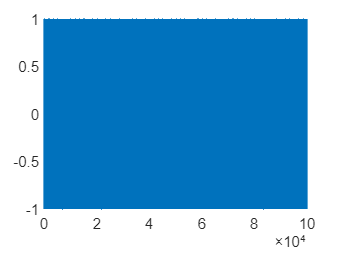

% to use the algorithm

% specify the number of games
N = 100000;

% return per episode
rets = zeros(N,1);

%%% Repeat for each episode
for i = 1:N

    %%% Initialise S
    % begin in the start state
    S = 2*ones(3);

    if(rand>0.5)
        S(randi(3),randi(3))=1;
    end

    % we want to keep going unless in a terminal state;
    term = false;

    %%% Repeat for each step of episode

    % reset episode return
    ret = 0;

    while term == false

        A = checkUnmarked(S);
        if isempty(A)
            term = true;
            R = 0;
            break
        end

        M = max(Q(S(1,1),S(1,2),S(1,3),S(2,1),S(2,2),S(2,3),S(3,1),S(3,2),S(3,3),:,:));
        argmaxa = find(Q(S(1,1),S(1,2),S(1,3),S(2,1),S(2,2),S(2,3),S(3,1),S(3,2),S(3,3),:,:) == M);
        ak = argmaxa(randi(length(argmaxa)));
        ac(2) = ceil(ak/3);
        ac(1) = mod(ak,3) + 3*(mod(ak,3)==0);

        %%% Take action A, observe Sp and R
        [Sp,R,term] = next_state(S,ac);

        %%% Update S
        S=Sp;

        % accumulate rewards for episode return
        ret = ret + R;

    end

    % record episode return
    rets(i) = ret;

end


figure
plot(rets);


length(find(rets==-1))

ans = 23669

length(find(rets==0))

ans = 1282

length(find(rets==1))

ans = 75049

function A = checkUnmarked(S)
    A = [];
    for i = 1:length(S(1,:))
        for j = 1:length(S(:,1))
            % unmarked grid
            if S(i,j) == 2
                A(end+1,:) = [i,j];
            end
        end
    end
end

function [S,R,term] = next_state(S,a)
% Determine the next state
% evaluate new state from the action
    % put a mark on S(a(1),a(2))
    S(a(1),a(2)) = 3;
    [R,term] = checkWinning(S);
    if term
        return
    end

    % opponent random action 
    % Possible actions A
    A = checkUnmarked(S);
    if isempty(A)
        term = true;
        R = 0;
        return
    end
    % choose a random action
    act = A(randi(length(A(:,1))),:);
    % opponent put a mark on S(act(1),act(2))
    S(act(1),act(2)) = 1;
    [R,term] = checkWinning(S);
end

function [R,term] = checkWinning(S)
    term = false;
    % opponent win 
    if(all(S(1,:) == 1) || all(S(2,:) == 1) || all(S(3,:) == 1))
        R = -1;
        term = true;
    end
    if(all(S(:,1) == 1) || all(S(:,2) == 1) || all(S(:,3) == 1))
        R = -1;
        term = true;
    end
    if((S(1,1) == 1 && S(2,2) == 1 && S(3,3) == 1) || (S(1,3) == 1 && S(2,2) == 1 && S(3,1) == 1))
        R = -1;
        term = true;
    end

    % algorithm win
    if(all(S(1,:) == 3) || all(S(2,:) == 3) || all(S(3,:) == 3))
        R = 1;
        term = true;
    end
    if(all(S(:,1) == 3) || all(S(:,2) == 3) || all(S(:,3) == 3))
        R = 1;
        term = true;
    end
    if((S(1,1) == 3 && S(2,2) == 3 && S(3,3) == 3) || (S(1,3) == 3 && S(2,2) == 3 && S(3,1) == 3))
        R = 1;
        term = true;
    end

    if (term == false)
        R = 0;
    end
end